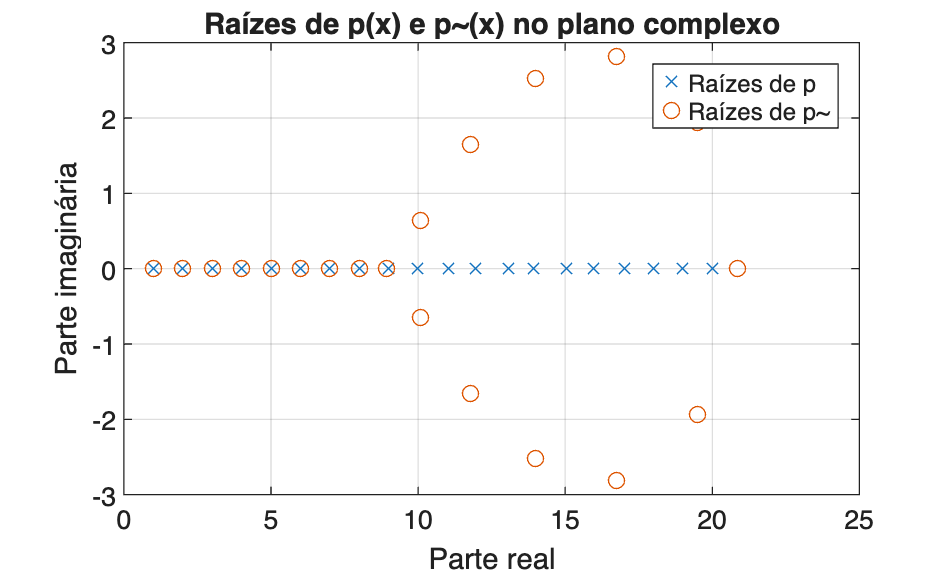

z_1: erro = 0.000000
z_2: erro = 0.000000
z_3: erro = 0.000000
z_4: erro = 0.000000
z_5: erro = 0.000002
z_6: erro = 0.000031
z_7: erro = 0.000495
z_8: erro = 0.008378
z_9: erro = 0.086896
z_10: erro = 0.653307
z_11: erro = 1.129284
z_12: erro = 1.660693
z_13: erro = 2.083378
z_14: erro = 2.519593
z_15: erro = 2.735470
z_16: erro = 2.916392
z_17: erro = 2.827311
z_18: erro = 2.457901
z_19: erro = 2.004005
z_20: erro = 0.847036


% b
grafico3b()

% (c)(ii) 
% Parâmetros
f = [0, 0.1, 0.8, 0.15, 0.1, 0, 0, 0, 0, 0];
s = [0.98, 0.96, 0.96, 0.94, 0.75, 0.51, 0.28, 0.12, 0.09];

m = 10;

% Matriz de Leslie
L = zeros(m);
L(1,:) = f;
for i = 1:m-1
    L(i+1,i) = s(i);
end

L

L =                    0   0.100000000000000   0.800000000000000   0.150000000000000   0.100000000000000                   0                   0                   0                   0                   0
   0.980000000000000                   0                   0                   0                   0                   0                   0                   0                   0                   0
                   0   0.960000000000000                   0                   0                   0                   0                   0                   0                   0                   0
                   0                   0   0.960000000000000                   0                   0                   0                   0                   0                   0                   0
                   0                   0                   0   0.940000000000000                   0                   0                   0                   0                   0            

% Pomos lambda^5 em evidência (ver relatório) e temos:
% q(lambda) = lambda^5 - 0.098*lambda^3 - 0.75264*lambda^2 
%           - 0.1354752*lambda - 0.08489779
q = [1, 0, -0.098, -0.75264, -0.1354752, -0.08489779];
r = roots(q);
lambda1_q = max(real(r))

lambda1_q =    1.021751559579279



% Verificação
lambdas = eig(L);
lambda1_eig = max(real(lambdas))

lambda1_eig =    1.021751560155810


% (c)(iii)
lambda1 = 1.0218; % pela subalinea (ii)
c7 = -0.75264;

% derivada p' em lambda1
dp_lambda1 = 10*lambda1^9 - 8*0.098*lambda1^7 - 7*0.75264*lambda1^6 - 6*0.1354752*lambda1^5 - 5*0.08489779*lambda1^4;

% numero de condição (alinea a) 
k = abs(c7) * lambda1^6 / abs(dp_lambda1)

k =    0.221579038592121


% encontrar epsilon
p = [1, 0, -0.098, -0.75264, -0.1354752, -0.08489779, 0, 0, 0, 0, 0];
for eps = 0:10^-6:1
    p_perturbado = p;
    p_perturbado(4) = p_perturbado(4) + eps;
    r = roots(p_perturbado);
    lambda1_tilde = max(real(r));
    if lambda1_tilde < 1
        fprintf('Epsilon: %.10f\n', eps);
        break
    end
end

Epsilon: 0.0710130000
